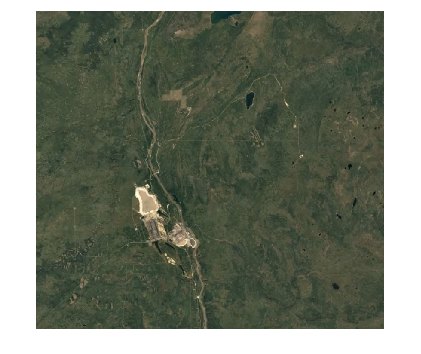

clf
n = 39;
im = imread('images/mining/mining_1984.png');
imsize = size(im);
imsize(4) = n;
ims = ones(imsize);
for i=1:n
    ims(:,:,:,i) = imread('images/mining/mining_' + string(1983+i) + '.png');
end
imshow(im)

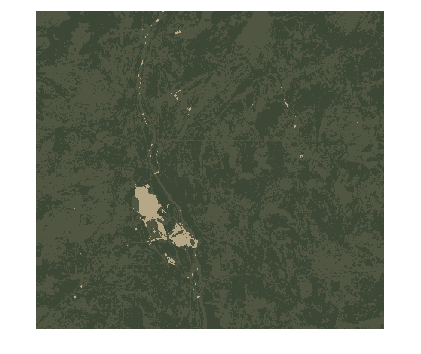

n_groups = 3;
[newim, means, p] = kmeansHSV(ims(:,:,:,1), n_groups);
imshow(newim)

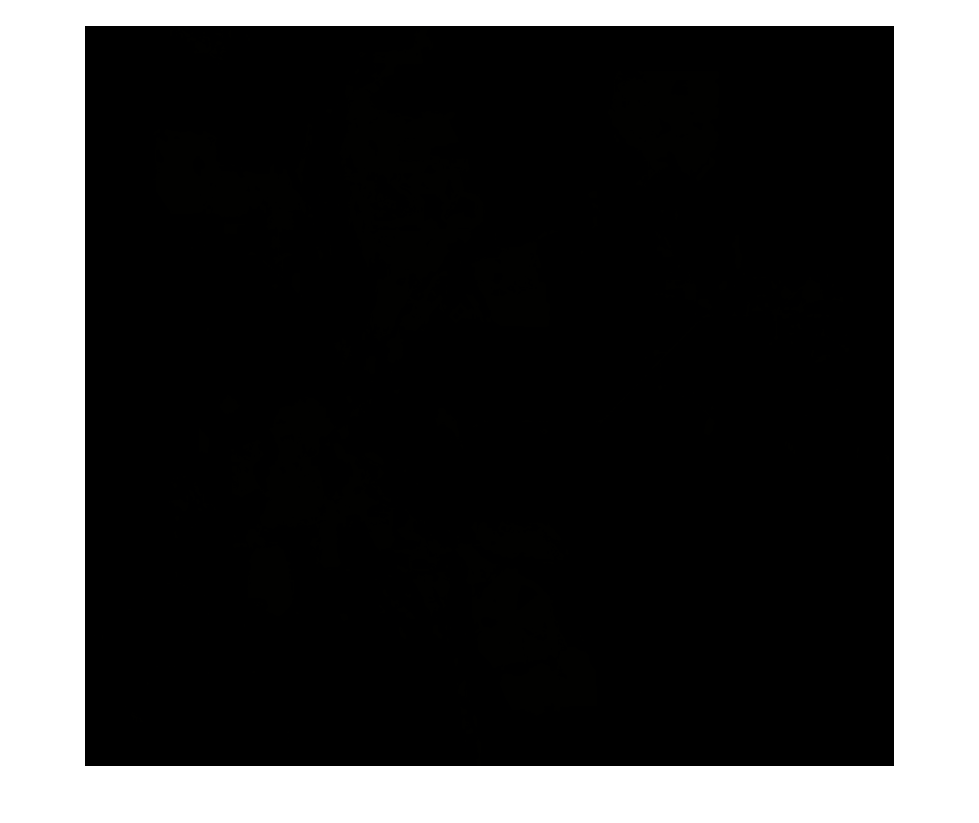


n_groups = 3;
newims = zeros(imsize);
ps = zeros([imsize(1)*imsize(2), n]);
group_counts = zeros([n,n_groups]);
for i=1:n
    [newims(:,:,:,i), means, ps(:,i)] = kmeansHSV(ims(:,:,:,i), n_groups);
    
    
    imshow(uint8(newims(:,:,:,i)))
    group_counts(i,1) = nnz(ps(:,i)==1);
    group_counts(i,2) = nnz(ps(:,i)==2);
    group_counts(i,3) = nnz(ps(:,i)==3);
end

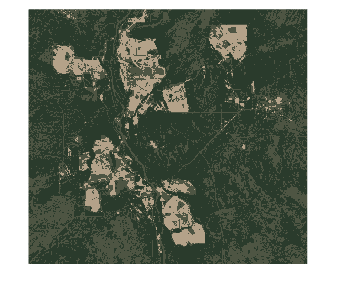

% [newim, h, s, v, p] = kmeansHSV(ims(:,:,:,1), n_groups);
for i=1:n
    imshow(uint8(newims(:,:,:,i)))
end

clf
means

means =     0.0954    0.2394  180.3904
    0.2344    0.2124   85.0473
    0.3562    0.2885   58.7616


size([1984:2022])

ans =      1    39


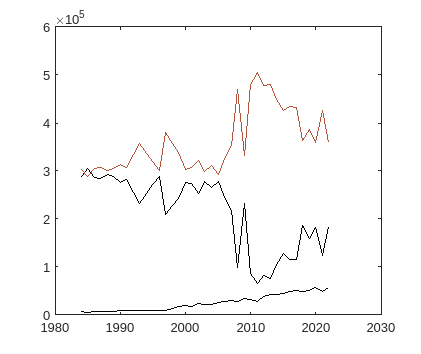

plot([1984:2022], group_counts(:,1)', "color", means(:,1)./255)
hold on
plot([1984:2022], group_counts(:,2)', "color", means(:,2)./255)
plot([1984:2022], group_counts(:,3)', "Color", means(:,3)./255)

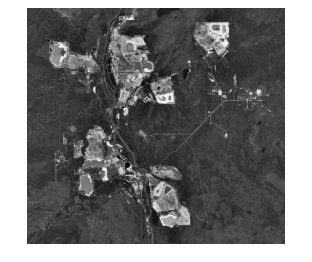

I1 = rgb2gray(im);
I1 = imgaussfilt(I1,1);
imshow(I1)


[C1, thresh] = edge(I1,'log', 0.01);
thresh

thresh = 0.0100

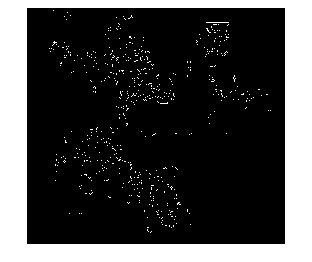

imshow(C1)

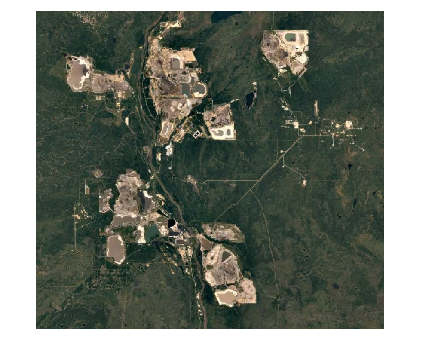

im = imread('images/mining/mining_2022.png');
imshow(im)

[newim, means, p] = kmeansHSV(im,3);
means

means =     0.0963    0.2487    0.6510
    0.2875    0.2162    0.2800
    0.4128    0.3824    0.2025


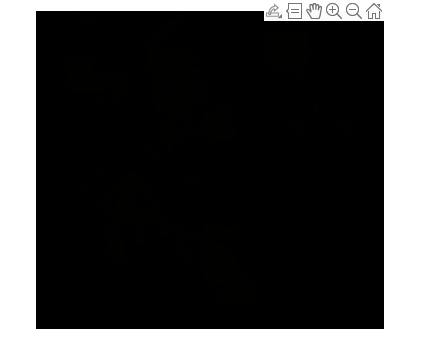

newim;
imshow(uint8(newim))


function [newimg, means, p1] = kmeansHSV(img, num)
    hsv1 = rgb2hsv(img);
    h1 = hsv1(:,:,1);
    h1 = reshape(h1.',1,[]);
    s1 = hsv1(:,:,2);
    s1 = reshape(s1.',1,[]);
    v1 = hsv1(:,:,3);
    v1 = reshape(v1.',1,[]);

    mean_idxs = randperm(length(h1), num);
    means = [h1(mean_idxs); s1(mean_idxs); v1(mean_idxs)]';
    p1 = zeros(size(h1));
    
    for i=1:20
        for j=1:length(p1)
            dists = sqrt((means(:,1) - h1(j)).^2 ...
                + (means(:,2) - s1(j)).^2 ...
                + (means(:,3) - v1(j)).^2);
            [maxd, idx] = min(dists);
            p1(j) = idx;
        end 
        for k=1:num
            group = (p1==k);
            % sum(group)
            sum_h = sum(group.*h1);
            sum_s = sum(group.*s1);
            sum_v = sum(group.*v1);
            means(k,1) = sum_h./nnz(group);
            means(k,2) = sum_s./nnz(group);
            means(k,3) = sum_v./nnz(group);
            % means
        end
    end
    means = sortrows(means,1);
    for j=1:length(p1)
        dists = sqrt((means(:,1) - h1(j)).^2 ...
            + (means(:,2) - s1(j)).^2 ...
            + (means(:,3) - v1(j)).^2);
        [maxd, idx] = min(dists);
        p1(j) = idx;
    end 

    h1new = zeros(size(h1));
    s1new = zeros(size(s1));
    v1new = zeros(size(v1));
    for k=1:length(means(:,1))
        group = (p1==k);
        h1new = h1new + group.*means(k,1);
        s1new = s1new + group.*means(k,2);
        v1new = v1new + group.*means(k,3);
    end
    
    hsv1new = zeros(size(hsv1));
    for i=1:length(hsv1(:,1))
        for j=1:length(hsv1)
            hsv1new(i,j,1) = h1new( (i-1)*length(hsv1)+j );
            hsv1new(i,j,2) = s1new( (i-1)*length(hsv1)+j );
            hsv1new(i,j,3) = v1new( (i-1)*length(hsv1)+j );
        end
    end
    newimg = uint8(hsv2rgb(hsv1new));
end